# Introducción a MATLAB

#### Autor: German Preciat, Universidad de Guadalajara

#### **Carrera: Ing. Biomédica**

#### **Materia: Ingeniería Metabólica**

#### Contacto: german.preciat@academicos.udg.mx

MATLAB es el nombre abreviado de “MATriz LABoratory”. Es un programa para realizar cálculos numéricos con vectores y matrices, y por tanto se puede trabajar también con números escalares (tanto reales como complejos), con cadenas de caracteres y con otras estructuras de información más complejas. 

Matlab es un lenguaje de alto rendimiento para cálculos técnicos, es al mismo tiempo un entorno y un lenguaje de programación. Uno de sus puntos fuertes es que permite construir nuestras propias herramientas reutilizables. Podemos crear fácilmente nuestras propias funciones y programas especiales (conocidos como M-archivos) en código Matlab, los podemos agrupar en Toolbox (también llamadas librerías): colección especializada de M-archivos para trabajar en clases particulares de problemas. 

Matlab, a parte del cálculo matricial y álgebra lineal, también puede manejar polinomios, funciones, ecuaciones diferenciales ordinarias, gráficos … 

El propósito de esta práctica es conocer algunas de las funciones básicas de `MATLAB`.

## 01. Operaciones **básicas **y **declaración **de variables

Las operaciones se pueden hacer desde la ventana de comando o en el "Live Editor".

2 + 45 % Suma
52 - 44 % Resta
4 * 12 % Multiplicación
225 / 15 % División
8^2 % Potencias
sqrt(81) % Raíz cuadrada
(12 + 2) * 4 % Paréntesis
12 + (2 * 4)
1 > 20 % Desigualdades (resultado en verdadero (1) o falso (0))
20 == 20
8 <= 20
1:10 % Series con intervalo de una unidad
1:2:7 % Series con intervalo de 2 unidades
5:-1:1 % Series con intervalo de -1 unidades

Un número, un vector, una matriz o el resultado de una operación pueden ser salvados en variables las cuales no pueden comenzar con números o símbolos. Los vectores y matrices se definen entre corchetes (`[]`) añadiendo un punto y coma (`;`) para indicar cada nuevo renglón. Adicionalmente, el punto y coma (`;`) al final de un comando evita que el resultado se imprima en la ventana de comandos.

a = 12; 
b = a * 2;
v1 = [1; 2]; % Vector de 2x1
v2 = 1:3; % Vector de 1x3
M1 = [1 2 3 4; 5 6 7 8]; % Matriz de 2x4
M2 = [1 2 3; 4 5 6; 7 8 9] % Matriz de 3x3 (sin el punto y coma se imprime el resultado)

Para conocer las dimensiones de un vector se utilizan diferentes funciones como:

- `numel`: Indica el número de elementos en la variable

- `length`: Indica la dimensión de la variable

- `size`: Indica las dimensiones de las variables

numel(M1) % Número de elementos en la matriz o vector
length(M1) % Máxima dimensión de la matriz o vector
size(M1) % Dimensiones de la matriz o vector
size(M1, 1) % Número de filas 
size(M1, 2) % Número de columnas

Consultar a la ayuda de MATLAB para saber más de todas las funciones. La ayuda se puede consultar en el signo de interrogación (?) en la parte superior derecha de la ventana o usando `help` en la ventana de comandos.

help size

## 02. **Operación **entre vectores y matrices

Para realizar operaciones entre vectores y matrices se deben de tomar en cuenta sus dimensiones. El carácter (`'`) es utilizado para trasponer una matriz o un vector.

v1 
v2
v3 = v2' % Trasponer vector
v4 = v3 * a % Multiplicación de vector por constante
M3 = M1' % Trasponer matriz
M4 = v1 * v2 % Multiplicación de vectores
M5 = M4 * b % Multiplicación de matriz por constante
M6 = [M2 v3] % Añadir una columna a una matriz

Para acceder a valores específicos dentro de un vector o una matriz, las coordenadas deben declarase dentro de un paréntesis. Los dos puntos (`:`) se utilizan para indicar a todos los valores de la dimensión señalada. El comando `end`, se utiliza para señala el fin del vector.

v1(1)
v4(end)
M1(1, 1)
M3(4, 2)
M4(1, :) % Todos los valores de la columna 1 en M4
M5(:, 3) % Todos los valores de la fila 4 en M5
M6(2:end, 2:3) % Matriz de 2x2 dentro de M6

## 03. Strings y arreglos

Los arreglos de `MATLAB` pueden contener tanto números como texto, definidas como strings. Un string debe estar definidos entre comillas simples (`'`) para ser reconocidos como texto. Para unir 2 strings pueden usar funciones como `strcat`, que concatena los textos o agregando las variables de texto entre corchetes (`[]`). 

Hay distintos tipos de arreglos:

- Arreglos en celdas

- Arreglos de estructuras

- Tablas

Los arreglos en celdas se declaran utilizando las llaves (`{}`) y tienen una estructura similar a matrices. Una variable numérica puede agregarse como texto al tipo de dato usando la funcion `num2str`. Los arreglos en celdas son útiles para exportar información.

str1 = 'Que onda';
str2 = ' mundo!';
strcat(str1, str2) % Concatenar
str3 = [str1 str2 ' todo bien?'] % Concatenar (otro metodo)
str4 = 'Este es el numero 2';
str5 = ['Y este es el numero ' num2str(a)];
array1 = {str4; str5} % El punto y coma indica una nueva línea
array2 = {'Dos', 2, '2'; 'Doce', a, num2str(a)} % Un arreglo con diferentes tipos de datos

Las tablas pueden generarse con la función `array2table`, la cual transforma un arreglo en una tabla. 

t1 = array2table(array2)
newNames = {'strLetra', 'numero', 'strNumero'};
t1.Properties.VariableNames = newNames
t2 = table;
t2.cellLines = {'Linea1'; 'Linea2'; 'Linea3'};
t2.noOfCells = (2:5:12)';
t2.atpProduction = v3

Los arreglos de estructura pueden utilizarse para guardar datos de forma estructurada en diferentes campos que a su vez pueden albergar más campos. Los arreglos de estructura tienen una forma similar a las tablas, cada campo es señalado con un punto (`.`).

sa1 = struct;
sa1.vector = v1;
sa1.matrix = M1;
sa1.string = str1;
sa1.array = array1;
sa1.table = t2;
sa1
% Nuevo struct array
sa2.vectors.v1 = v1;
sa2.vectors.v2 = v1 + 1;
sa2.matrices.M1 = M1;
sa2.matrices.M2 = M1 * 2;
sa2
sa2.vectors
sa2.vectors.v1
sa2.vectors.v1(2)

## 04. Figuras

Matlab cuenta con una variedad de funciones para visualizar datos, algunos ejemplos son:

- `plot`

- `bar`

- `scatter`

- `heatmap`

El comando `hold on` se usa para sobreponer una o más graficas en una misma figura. Para dejar de sobreponer graficas se ejecuta el comando `hold off`. Adicionalmente, `MATLAB` cuenta con diferentes funciones para personalizar una figura, como agregar título, nombre a los ejes, color de la gráfica, ancho de la gráfica, leyenda, etc.

figure
hold on
plot(v2, v3)
plot(v2, v3 * 2, 'g', 'LineWidth', 2, 'LineStyle','--')
title('Mi grafica')
xlabel('Eje X')
ylabel('Eje Y')
legend({'Grafica 1', 'Grafica 2'})
hold off

Además, con la función `subplot`, es posible de agrupar diferentes figuras para su visualización. Se ejecuta como `subfigure(noDefilas, noDecolumnas, noDeFigura)`. 

figure
% plot
subplot(2, 2, 1)
hold on
plot(v2, v3)
plot(v2, v3 * 2, 'g', 'LineWidth', 2, 'LineStyle','--')
title('Mi grafica')
xlabel('Eje X')
ylabel('Eje Y')
legend({'Grafica 1', 'Grafica 2'})
hold off

% bar
subplot(2, 2, 2)
bar(v2)

% scatter
subplot(2, 2, 3)
hold on
scatter(M5(:, 1), M4(:, 1), 'black', 'filled')
scatter(M4(:, 1), M5(:, 1), 'blue')
scatter(M5(:, 1), M5(:, 1), 'red', 'filled')
legend({'Punto 1', 'Punto 2', 'Punto 3'})
hold off

% heatmap
subplot(2, 2, 4)
heatmap(M5);
title('Numero de células')
xlabel('Replicados')
ylabel('Tratamiento')

Para saber más de todas las características de las figuras consultar la ayuda de `MATLAB`.

## 05. Estructuras de control

En lenguajes de programación, las **estructuras de control** permiten modificar el flujo de ejecución de las instrucciones de un programa.

Con las estructuras de control se puede:

- De acuerdo con una condición, ejecutar un grupo u otro de sentencias (If-Else)

- Ejecutar un grupo de sentencias un número determinado de veces (For)

- De acuerdo con el valor de una variable, ejecutar un grupo u otro de sentencias (Switch-Case)

- Ejecutar un grupo de sentencias **solo cuando** se cumpla una condición (While)

A continuación, algunos ejemplos de su uso.

### IF

Si `a` es mayor que 32 la variable `c` será igual a la variable `a`, sino será igual a 32.

if a > 32 
    c = a;
else
    c = 32;
end
c

### FOR

Crear una matriz que al sumarla con M4 todos los valores sean igual a 12. 

Con la función `zeros` es posible generar un vector o matriz con las dimensiones definidas por el usuario. Otras funciones que se usan de forma similar son `one` (crea una matriz o vector con las dimensiones indicadas) o `cell` (crea celdas vacías con las dimensiones indicadas).

% Conocer las dimensiones de M4
[m, n] = size(M4);
M7 = zeros(m, n); % También es posible escribir funciones dentro de funciones como 'M7 = zeros(size(M4))'

% Recorrer cada fila de M4
for i = 1:m
    % Recorrer cada columna de M4
    for j = 1:n
        % Agregar nuevo valor
        M7(i, j) = 12 - M4(i, j);
    end
end
M4 + M7

### SWITCH

Muestra texto diferente condicionalmente, dependiendo de un valor ingresado en el símbolo del sistema. La función `input` permite que el usuario ingrese un valor. La función `dispaly` se utiliza para imprimir el resultado (como omitir un punto y coma).

n = input('Ingresa un numero: '); % Input seleccionado por el usuario
switch n
    case -1
        disp('menos uno')
    case 0
        disp('cero')
    case 1
        disp('uno')
    otherwise
        disp('otro valor')
end

### WHILE

Calcular el factorial de 10 usando `while`. 

n = 10;
f = n;
while n > 1
    n = n-1;
    f = f*n;
end
disp(['n! = ' num2str(f)])

## 06. Scripts y funciones

Las funciones y scripts son el mecanismo que ofrece MATLAB para simplificar la escritura de programas o la carga de datos iniciales. Se pueden escribir directamente en la línea de comandos de MATLAB, o en ficheros externos. En ese caso los scripts y las funciones se invocan exactamente igual que cualquier otra función predefinida de MATLAB. La única condición es que esos ficheros se encuentren en un directorio dentro del path de MATLAB.

Para más información sobre el path de búsqueda de ficheros de MATLAB consultar:

help addpath

Los ficheros de scripts y funciones de MATLAB tienen extensión ".m", mientras que los LiveScripts tienen extensión ".mlx".

Un script es como cada una de las secciones de esta práctica, mientras que las funciones tienen el siguiente formato:

`function`` variableRetornada ``=`` nombreFuncion``(``listaArgumentos``)`

`    cuerpoDeFuncion`

`end`

El formato tiene los siguientes campos:

- Empiezan con la palabra clave function que indica el inicio de la declaración de una función de MATLAB.

- Opcionalmente sigue la declaración de las variables retornadas. Puede ser una única variable (de cualquier tipo permitida en MATLAB) o una lista de variables entre corchetes (`[]`). Las variables pueden ser de distintos tipos.Si no existe la lista de variables, tampoco deberá aparecer el signo igual y la función no devolverá ningún valor.

- El nombre de la función

- Opcionalmente sigue la lista de argumentos entre paréntesis () y separados por comas. Si no aparece la lista de argumentos la función no tendrá parámetros de entrada.

- A continuación, sigue el código o cuerpo de la función.

- La función termina con la palabra end.

La función es un ejemplo usando elementos que se revisaron en las secciones pasadas.

help linearEquationsSolver
matricesAndVectors = sa2;
printLevel = 0;
systemSolution = linearEquationsSolver(matricesAndVectors, printLevel);
linearEquationsSolver(matricesAndVectors, 1);
linearEquationsSolver(matricesAndVectors, 2);

## Importar datos

Con la función `save` se salvan datos específicos o todo el Workspace en el directorio indicado. El comando `pwd` imprime el directorio en donde nos encontramos.

directorioActual = pwd;
save([directorioActual filesep 'tablaDeCelulas'], 't2') % Salva la tabla t2
save([directorioActual filesep 'practica1EspacioDeTrabajo']) % Salva todo
clear % Borra todo el espacio de trabajo
load([pwd filesep 'practica1EspacioDeTrabajo.mat'])
clear

## Ejercicio

Tienes diferentes muestras de microbiota humana donde se encuentran diferentes organismos, entre ellos bacterias, arqueas, hongos, protistas y virus. Estas muestras te seguirán llegando frecuentemente. Sin embargo, solo 1 muestra puede ser analizada a la vez en el espectrómetro de masas. El laboratorio se especializa en bacterias arqueas y protistas y tu obtienes cuantos pares de base se identificaron de cada organismo en cada pozo. 

Necesitas desarrollar una función que identifique la muestra con mayor expresión de bacterias arqueas y protistas, además de generar una imagen para mostrarle a los jefes en una presentación.

### Paso 1 - Definir variables

Las muestras las tienen en una caja de cultivo de 6 pozos:

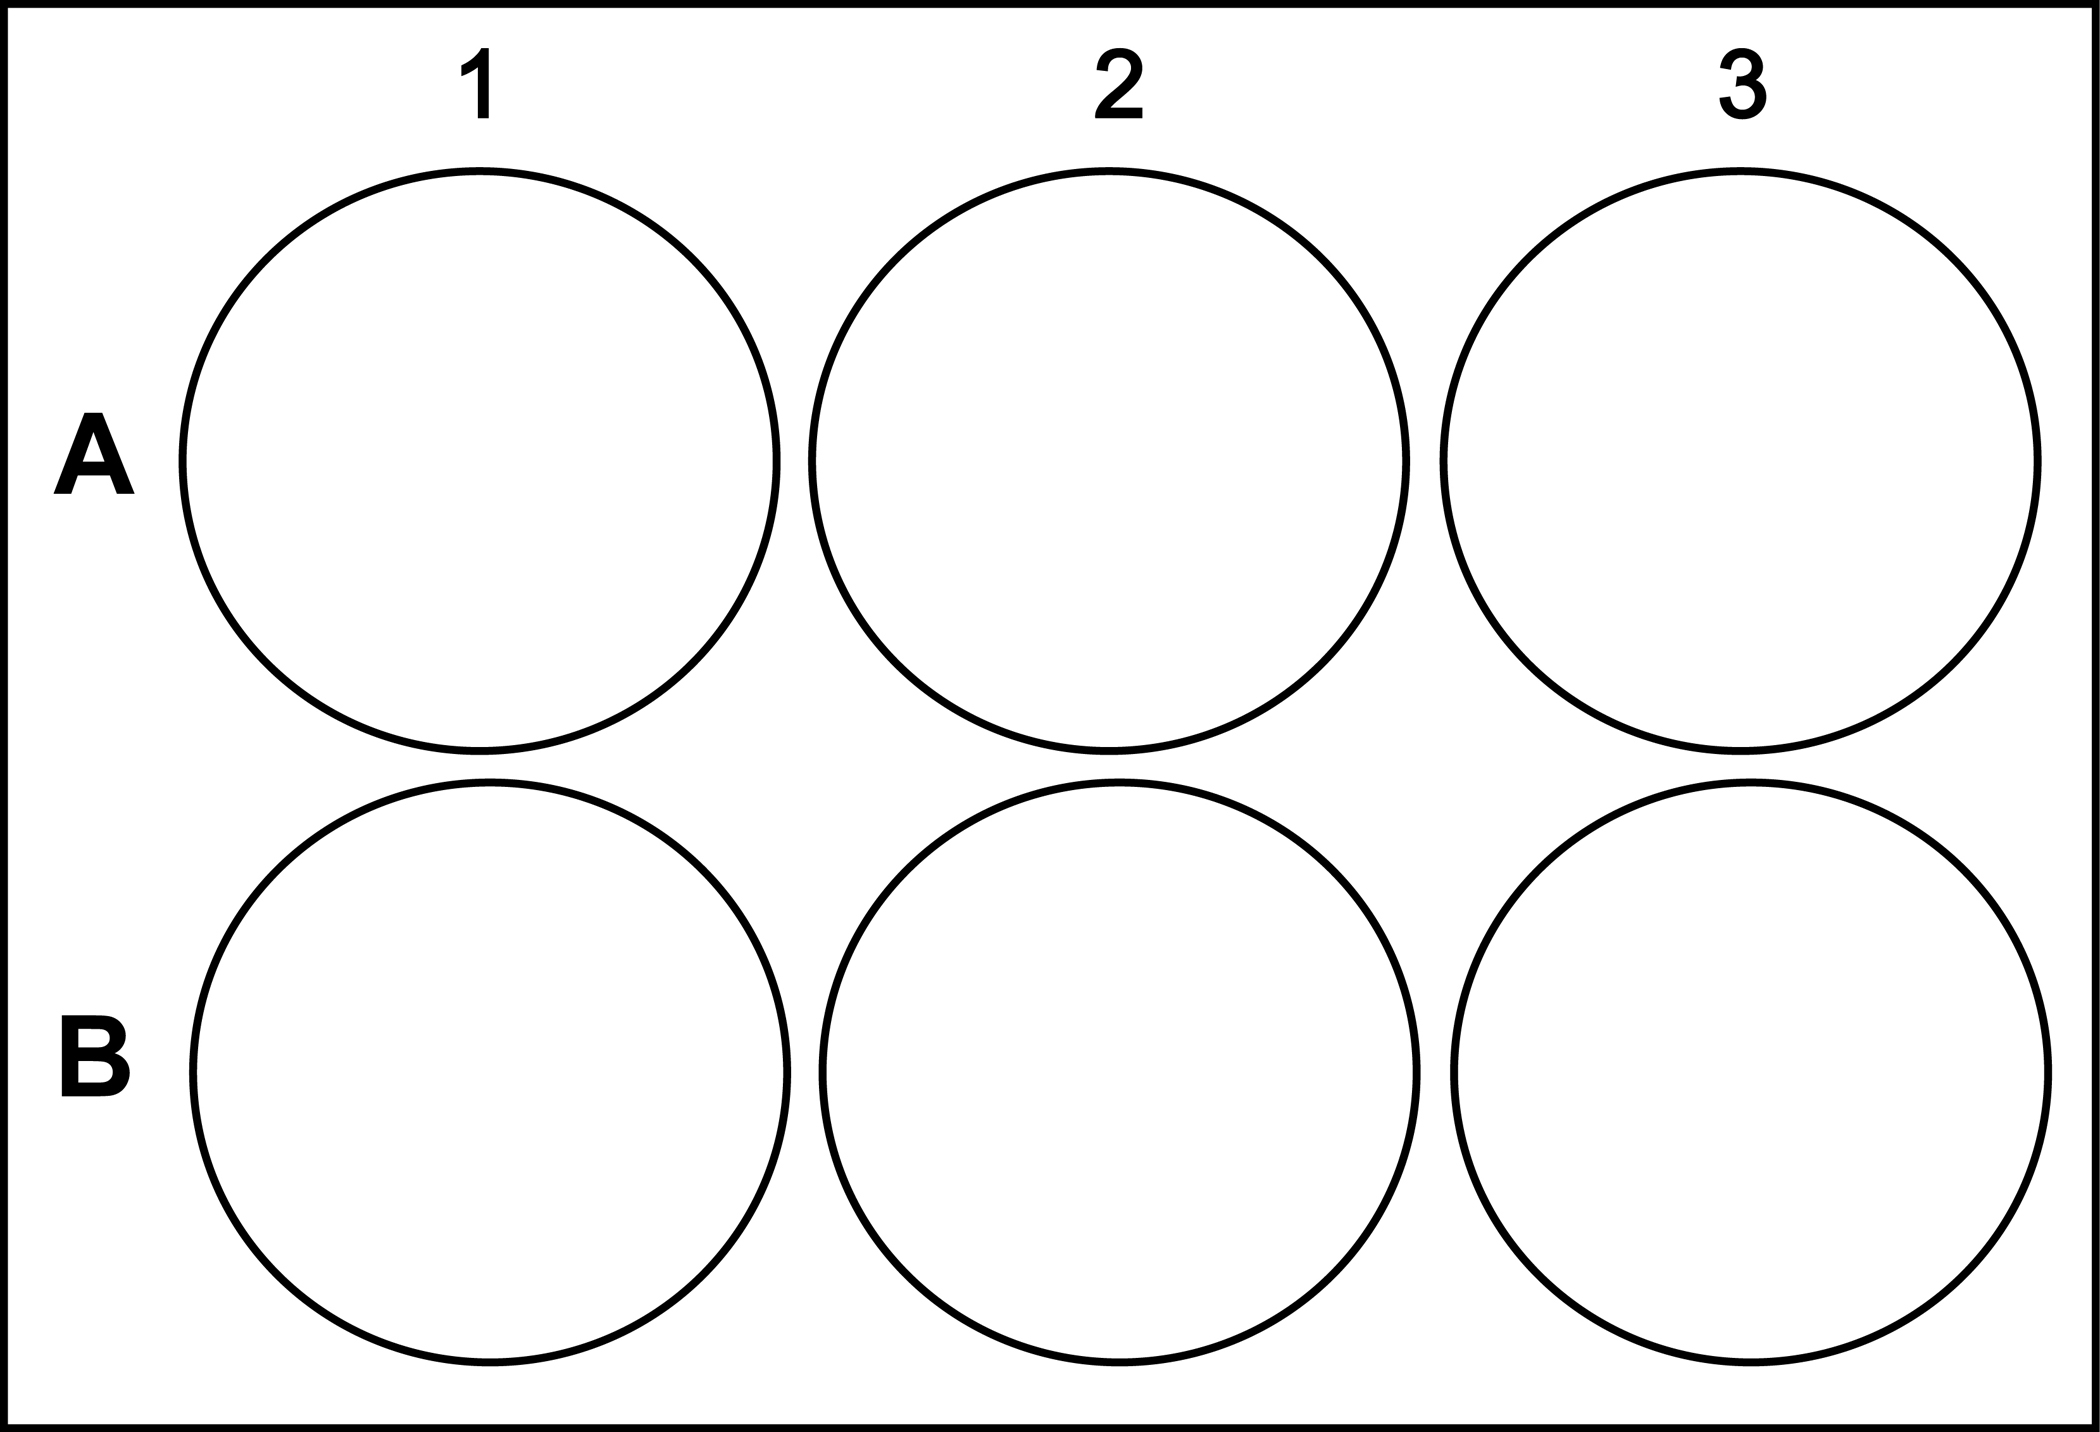

Crea un arreglo (e.g., `pozos`) con 6 strings que contenga la etiqueta de los `pozos` (a1, a2, a3, b1, b2 y b3). Pista ctrl + f y busca "*array1*".

wells = {'a1'; 'a2'; 'a3'; 'b1'; 'b2'; 'b3'};

Crea una matriz (`A1`) de 6x5 (muestras x organismos) con los pares de base identificados en cada muestra con los datos que están en la siguiente matriz en kilobase (kb):

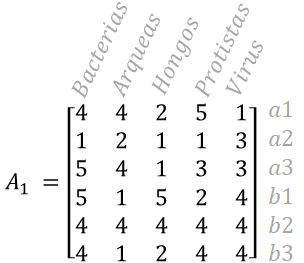

Pista ctrl + f y busca "*M1 = [*".

A1 = [4 4 2 5 1; 1 2 1 1 3; 5 4 1 3 3; 5 1 5 2 4 ; 4 4 4 4 4; 4 1 2 4 4];

La siguiente muestra llego por replicado (`M1` y `M2`). Necesitas definir `M1` y `M2 `y sacar el promedio de la expresión entre ambas muestras (`A2`). Pista ctrl + f y busca "*M7*".

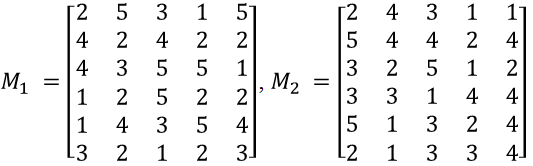

M1 = [2 5 3 1 5; 4 2 4 2 2; 4 3 5 5 1; 1 2 5 2 2; 1 4 3 5 4; 3 2 1 2 3];
M2 = [2 4 3 1 1; 5 4 4 2 4; 3 2 5 1 2; 3 3 1 4 4; 5 1 3 2 4; 2 1 3 3 4];
A2 = (M1 + M2) / 2;

Ahora te llegaron 4 muestras más  (`A3`, `A4`, `A5`, `A6`), utiliza la función "`randi"` para inventarte las kb encontradas en cada muestra y su rango sea de entre 1-5kb. Revisa la ayuda de MATLAB ya sea online o en la parte superior derecha (help `randi` no sirve de mucho XD).

A3 = randi(5, 6, 5);
A4 = randi(5, 6, 5);
A5 = randi(5, 6, 5);
A6 = randi(5, 6, 5);

### Paso 2 - Hacer un script que resuelva la **ecuación **$A\cdot x=b$

Ya que queremos la muestra más que tenga más pares de bases de organismos específicos necesitamos:

- Definir `x` como: 

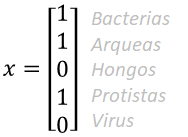

(recuerda que no es lo mismo $m\cdot n$ que $n\cdot m$)

- Encontrar $b$ usando `A1 en `$A\cdot x=b$

- Encontrar la muestra más interesante para el laboratorio, usar la ayuda de `max`, `find` y el doble signo de igualdad `==`.

% Definir x
x = [1; 1; 0; 1; 0];
% Encontrar b
b = A1 * x;
% Encontrar el valor mas grande
bestWellIdx = find(b == max(b));

### Paso 3 - Hacer una funcion que imprima los resultados

- Guardar el arreglo `wells` en la estructura `experimentalData; `Pista ctrl + f y busca `"`*sa1*`"`

- Guardar las matrices `A1`, `A2`, `A3`, `A4`, `A5` y `A6` en el arreglo estructura `experimentalData`

- Guardar el vector `x` indicando nuestros organismos de interés en la estructura `experimentalData`

- Hacer una función de la forma "wellSelectedPerSample` = findTheBestSample(experimentalData, printLevel)`"; Pista usar `open linearEquationsSolver`

- Incluir descripción de la función

- `wellSelectedPerSample` señala el pozo que se debe de utilizar por muestra (pozo: $a_n$ o $b_n$; Paso 2 y lo ultimo de la *Seccion 02. Operación entre vectores y matrices*).

- `printLevel` igual 1 imprime una tabla que indique la expresión combinada de los organismosde interés por cada muestra en cada pozo y algunos mensajes del progreso de la función.

- `printLevel` igual 2 imprime una figura señalando la expresión combinada de los organismos de interés por muestra ($b$ en $A\cdot x=b$; usar `subplot` y `heatmap`). Reorganizar $b$ de $1\times 6$ a $3\times 2$ para representar una caja de cultivo.

experimentalData.wells = wells;
experimentalData.samples.A1 = A1;
experimentalData.samples.A2 = A2;
experimentalData.samples.A3 = A3;
experimentalData.samples.A4 = A4;
experimentalData.samples.A5 = A5;
experimentalData.samples.A6 = A6;
experimentalData.x = x;
printLevel = 0;
wellSelectedPerSample = findTheBestSample(experimentalData, printLevel);
printLevel = 1;
wellSelectedPerSample = findTheBestSample(experimentalData, printLevel);
printLevel = 2;
wellSelectedPerSample = findTheBestSample(experimentalData, printLevel);